# EE115 Lab 4

# Buddy Ugwumba

- Compute and plot "$P_{\mathrm{uK}}$ versus K" and "1 - $P_{\mathrm{uK}}$ versus K" for various $\beta$

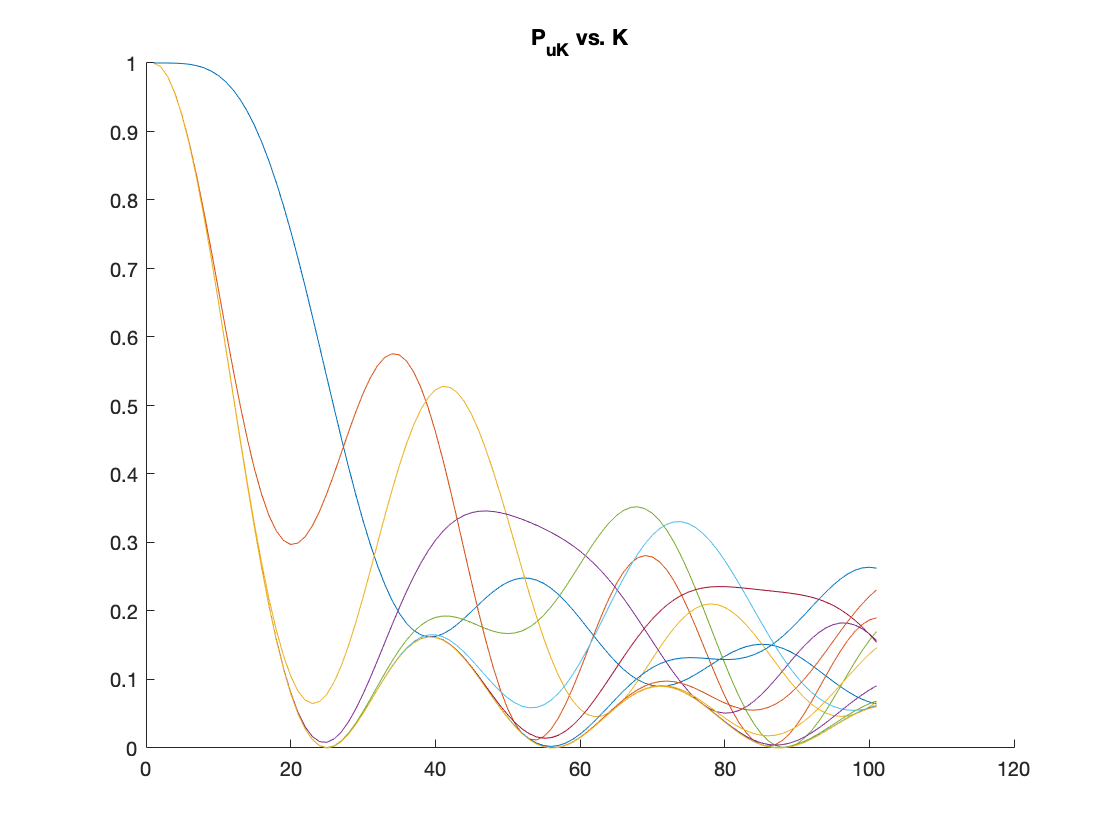

clf
%various beta
beta = 0:0.1:10;
K = 100;
n = 1:1:K+1;
uK_t = besselj(0,beta);
% For Loop
for i = n
    value = besselj(i,beta);
    P_uk = uK_t.^2 + 2*(value.^2);
    hold on
    plot(n, P_uk)
end
title('P_{uK} vs. K')
hold off

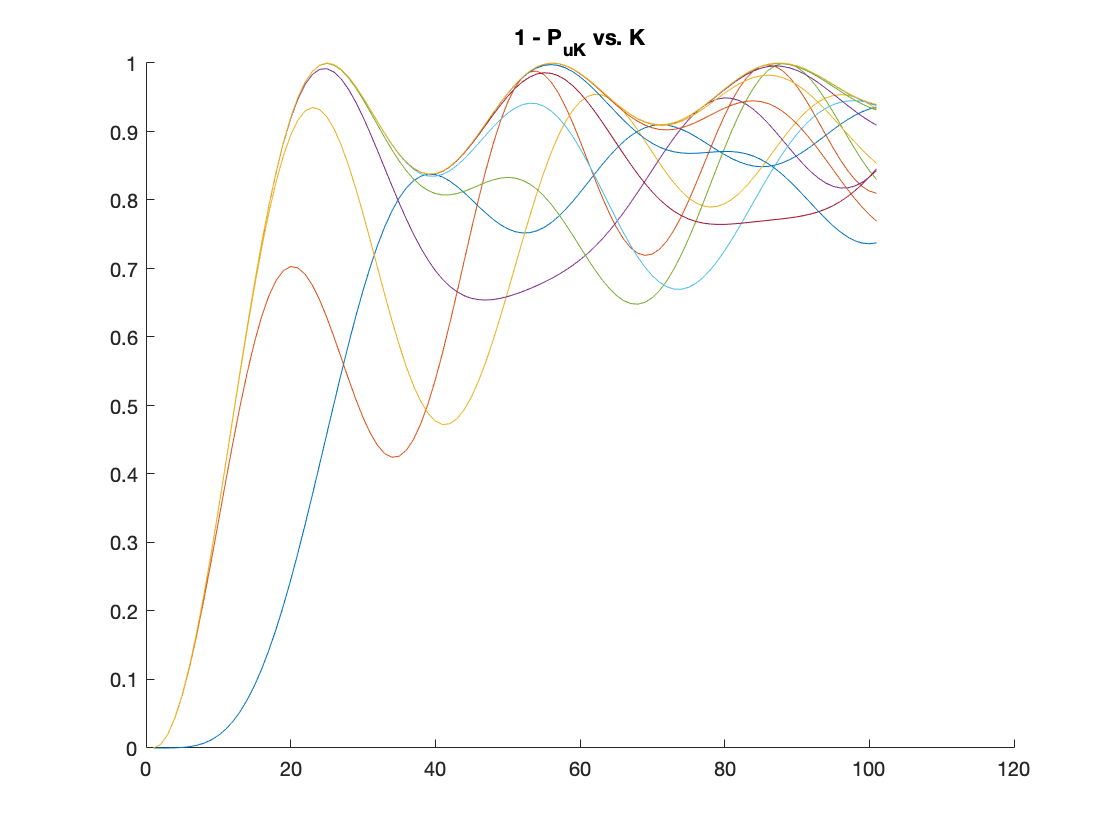

figure
for i = n
    value = besselj(i,beta);
    P_uk = uK_t.^2 + 2*(value.^2);
    P_uK = 1 - P_uk;
    hold on
    plot(n, P_uK)
end
title('1 - P_{uK} vs. K')

- Explain why 1 - $P_{\mathrm{uK}}$ is the power of the error function $u\left(t\right)-u_K \left(t\right)$

Consider the **FM signa**l:


$$u_{\mathrm{FM}} \left(t\right)=\mathrm{cos}\left(2\pi f_c t+2\pi k_f \int_0^t m\left(\tau \right)d\tau \right)$$


of a **single tone message** $m\left(t\right)\;=\;\mathrm{cos}\left(2\pi f_m t\right)$. Its **complex envelope** with respect $2\pi f_c t$ is $u\left(t\right)=e^{j\beta \mathrm{sin}\left(2\pi f_m t\right)}$. $u\left(t\right)$is a **complex function **of a** complex variable**. Meaning the input and output $\left(t,u\right)$ are only dependent upon the complex function $t+\mathrm{ju}$ ($e^{j\beta \mathrm{sin}\left(2\pi f_m t\right)}$becomes a complex function by way of **Euler's formula**). 

In mathematics, the **error function** (also called the **Gauss error function**) is the complex function of a complex variable defined as 


$$\mathrm{erf}\;z=\frac{2}{\sqrt{\pi }}\int_0^t e^{-t^2 \mathrm{dt}}$$


The error function is an **entire function** (meaning it has a finite sum) with the only singularity at **infinity**. At infinity, the error function equals 1.

In communication systems, this formula is known as **power of the error functio**n. The power of a finite signal is always 0. Only** periodic signals** have a power greather than zero. To determine that power integrate over the period $\left\lbrack -\frac{T}{2},\frac{T}{2}\right\rbrack$ then multiply by $\frac{1}{T}$ as $T\to \infty$.  The defining integrand of the power of the error function cannot be evaluted in closed form in terms of elementary functions, but by expanding the integrand into its Maclaurin series. Interestingly, the coefficents of the complex enevelope when expanded is the Bessel Function of the nth order. 

If we take the fourier transform of 

$u\left(t\right)$ and $u_K \left(t\right)$ are two closely related functioons. Therefore the **complememtary error function** is $\mathrm{erf}c\;t=1-\mathrm{erf}\left(t\right)$ 

The total power of $u\left(t\right)$, which is the complex envelope of $u_{\mathrm{FM}} \left(t\right)$, is equal to 1. The limit, as K approaches infinity, of the fourier series expansion of $u_K \left(t\right)$ is also one. Therefore, the total power minus the power of various integer multiples of the same complex envelope (given the condition that we neglect all orders when $|n|>K$) gives us the error function $u\left(t\right)-u_K \left(t\right)$.  

2. Explain why the bandwidth of $u\left(t\right)$ is approximately equal to $B_m =f_m \left(\beta +1\right)$.

The bandwidth of $u\left(t\right)=B_u$ if $J_n \left(\beta \right)$ for $|n|>K$ can all be neglected. $B_u ={\mathrm{Kf}}_m ={\mathrm{KB}}_m$. Performing algebra we get $B_m =f_m$. This leaves us with the equation $W=2f_m \left(\beta +1\right)$. Since we are only interested in the positive values of spectrum, we divide the bandwidth by 2. Therefore, the bandwidth of $u\left(t\right)=f_m \left(\beta +1\right)$.